clc
clear
close

% Sägeband-Geometrie
L = 0.200; % Länge des Sägebands (x-Richtung, mm)
b = 0.034;  % Breite des Sägebands (y-Richtung, mm)
h = 0.0011; % Dicke des Sägebands (z-Richtung, mm)


num_nodes_x = 100; % Anzahl der Knoten in x-Richtung
num_nodes_y = 15; % Anzahl der Knoten in y-Richtung
num_nodes_z = 4; % Anzahl der Knoten in z-Richtung

% Materialmatrix
E_modul = 2.1e8 ; %210000; % N/mm²; Sollte eigentlich in N/m² sein -> Faktor 100 zu klein
v = 0.3;


rho = 7.83e3; %
sigma_x = 3e8; %300; N/m²
sigma_y = 0; 
sigma_z = 0; 


D_const = E_modul / ((1 + v) * (1 - (2 * v)));


% Schrittweiten
dx = L / (num_nodes_x - 1);
dy = b / (num_nodes_y - 1);
dz = h / (num_nodes_z - 1);

% Koordinaten der Knoten erzeugen
node_coords = [];
for k = 0:(num_nodes_z - 1)
    for j = 0:(num_nodes_y - 1)
        for i = 0:(num_nodes_x - 1)
            x = i * dx;
            y = j * dy;
            z = k * dz;
            node_coords = [node_coords; x, y, z];
        end
    end
end
% Anzahl der Knoten
num_nodes = size(node_coords, 1);

% Elementzuweisung
elements = [];
nodes_per_row = num_nodes_x + 1;
nodes_per_layer = (num_nodes_y + 1) * (num_nodes_x + 1);

for k = 1:num_nodes_z-1  % Iteration in z-Richtung
    for j = 1:num_nodes_y-1  % Iteration in y-Richtung
        for i = 1:num_nodes_x-1  % Iteration in x-Richtung
            % %Berechnung der Knotenindizes
            n1 = i + (j - 1) * num_nodes_x + (k - 1) * num_nodes_x * num_nodes_y;
            n2 = n1 + 1;
            n3 = n1 + num_nodes_x + 1;
            n4 = n1 + num_nodes_x;
            n5 = n1 + num_nodes_x * num_nodes_y;
            n6 = n2 + num_nodes_x * num_nodes_y;
            n7 = n3 + num_nodes_x * num_nodes_y;
            n8 = n4 + num_nodes_x * num_nodes_y;

            elements = [elements; n1, n2, n3, n4, n5, n6, n7, n8];
        end
    end
end

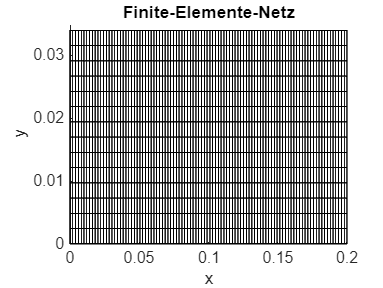


% Anzahl der Elemente
num_elements = size(elements, 1);

% Netz mit Knoten- und Elementnummern plotten
figure;
hold on;

% Edge-Definition für Hexaeder
edges = [
    1, 2; 2, 3; 3, 4; 4, 1;  % Vorderseite (unten)
    5, 6; 6, 7; 7, 8; 8, 5;  % Rückseite (oben)
    1, 5; 2, 6; 3, 7; 4, 8   % Vertikale Kanten
    ];

% Schleife über alle Elemente
for e = 1:size(elements, 1)
    element_nodes = elements(e, :);  % Knoten des Elements
    coords = node_coords(element_nodes, :);  % Koordinaten der Knoten

    % Zeichne die Kanten des Elements
    for edge = 1:size(edges, 1)
        plot3(coords(edges(edge, :), 1), coords(edges(edge, :), 2), coords(edges(edge, :), 3), 'k');
    end

end

xlabel('x');
ylabel('y');
zlabel('z');
title('Finite-Elemente-Netz');
hold off;

D = D_const * [1-v, v, v, 0, 0, 0;
               v, 1-v, v, 0, 0, 0;
               v, v, 1-v, 0, 0, 0;
               0, 0, 0, (1-2*v)/2, 0, 0;
               0, 0, 0, 0, (1-2*v)/2, 0;
               0, 0, 0, 0, 0, (1-2*v)/2];


% Globale Matrizen initialisieren
K_global = sparse(3 * num_nodes, 3 * num_nodes); % Materialsteifigkeitsmatrix
M_global = sparse(3 * num_nodes, 3 * num_nodes); 
Vol_Jacobi = 0;

% Schleife über alle Elemente
for e = 1:size(elements, 1)
    element_nodes = elements(e, :);
    coords = node_coords(element_nodes, :);

    [Ke_material, Me_material] = material_stiffness(coords, D, rho);
    
    for i = 1:8
        for j = 1:8
            global_i = (element_nodes(i) - 1) * 3 + (1:3);
            global_j = (element_nodes(j) - 1) * 3 + (1:3);
            local_i = (i - 1) * 3 + (1:3);
            local_j = (j - 1) * 3 + (1:3);

            % Assembly
            K_global (global_i, global_j) = K_global (global_i, global_j) + Ke_material(local_i, local_j);
            M_global (global_i, global_j) = M_global (global_i, global_j) + Me_material(local_i, local_j);
        end
    end
end


%fixed_nodes = find(X(:, 1) == 0 | X(:, 1) == L);  % Alle Knoten an x = 0 oder x = L
tolerance = 1e-6;  % Toleranz für numerische Vergleiche
fixed_nodes = find(abs(node_coords(:, 1)) < tolerance | abs(node_coords(:, 1) - L) < tolerance);

DOFs_per_node = 3;       % Freiheitsgrade pro Knoten (x, y, z)
N_DOFs = num_nodes * DOFs_per_node; % Gesamtanzahl der Freiheitsgrade

fixed_DOFs = [];
for node = fixed_nodes
    fixed_DOFs = [fixed_DOFs, (node-1) * DOFs_per_node + (1:DOFs_per_node)];
end

% Setze Spalten und Zeilen der fixierten DOFs auf 0
K_global(fixed_DOFs, :) = 0;       % Setze betroffene Zeilen auf 0
K_global(:, fixed_DOFs) = 0;       % Setze betroffene Spalten auf 0
K_global(sub2ind(size(K_global), fixed_DOFs, fixed_DOFs)) = 1; % Diagonalelemente auf 1 setzen


condest(K_global)

ans = 1.0662e+09

condest(M_global)

ans = 8.0000

total_mass = sum(M_global(:));
disp(['Gesamtmasse: ', num2str(total_mass)]);

Gesamtmasse: 0.058568


% Verallgemeinertes Eigenwertproblem lösen
[V, D_eig] = eigs(K_global, M_global, 15, 'sm');  % 10 kleinste Eigenfrequenzen
disp('Eigenfrequenzen:');

Eigenfrequenzen:


disp(real(sqrt(diag(D_eig))) / (2 * pi));  % Umrechnung in Hz

   12.4163
   32.7295
   34.2111
   67.0468
   68.8152
  103.8739
  103.8739
  103.8739
  103.8739
  110.8030
  110.9157
  146.8998
  146.8998
  146.8998
  160.8101



function [Ke, Me_diag] = material_stiffness(coords, D, rho)
    % Initialisiere Matrizen
    Ke = zeros(24, 24); % Materialsteifigkeitsmatrix
    Me = 0;             % Massematrix
    
    % Gauss-Punkte (2 Punkte pro Richtung)
    gauss_points = [-sqrt(1/3), sqrt(1/3)];

    % Anzahl der Knoten und Freiheitsgrade
    num_nodes = 8;          % 8 Knoten für ein Brick-Element
    dof_per_node = 3;       % 3 Freiheitsgrade pro Knoten (x, y, z)
    total_dofs = num_nodes * dof_per_node; % Gesamtanzahl der Freiheitsgrade

    % Iteration über die Gauss-Punkte
    for i = 1:2
        for j = 1:2
            for k = 1:2
                % Gauss-Punkt-Koordinaten
                r = gauss_points(i);
                s = gauss_points(j);
                t = gauss_points(k);

                % Berechnung für den aktuellen Gauss-Punkt
                [J_det, B, N, dN_dxyz] = brick8_Td(coords, r, s, t);
                Ke = Ke + (B' * D * B) * J_det; % Materialsteifigkeit
                Me = Me + rho * J_det;         % Massematrix (Gewicht)
            end
        end
    end

    % Diagonalisierte Massenmatrix
    Me_diag = eye(24) * (Me / 24);
end

% Saw Geometry
L = 0.200; % Length of the saw (x-direction, m)
b = 0.034; % Width of the saw (y-direction, m)
h = 0.0011; % Thickness of the saw (z-direction, m)

% Discretization
num_nodes_x = 100; % Number of nodes in x-direction
num_nodes_y = 15; % Number of nodes in y-direction
num_nodes_z = 4;  % Number of nodes in z-direction

dx = L / (num_nodes_x - 1);
dy = b / (num_nodes_y - 1);
dz = h / (num_nodes_z - 1);

% Total number of nodes
num_nodestotal = num_nodes_x * num_nodes_y * num_nodes_z;

% Initialize the force matrix
F_global = zeros(3 * num_nodestotal, 1);

% Force parameters
force_magnitude = 30; % Magnitude of force (N)
force_spacing = 0.02; % Spacing between forces (periodicity in x-direction)

% Initialize grid coordinates
[x, y, z] = meshgrid(0:dx:L, 0:dy:b, 0:dz:h);

% Reshape the coordinates into vectors for easier plotting and calculations
x = reshape(x, [], 1);
y = reshape(y, [], 1);
z = reshape(z, [], 1);

% Identify force application points
force_nodes_bottom = [];
force_nodes_top = [];
for i = 1:length(x)
    % Apply forces periodically along x at top and bottom edges (y = 0 and y = b)
    if mod(x(i), force_spacing) < dx
        if abs(y(i)) < 1e-6  % Nodes at y = 0 (bottom edge)
            force_nodes_bottom = [force_nodes_bottom; i];
        elseif abs(y(i) - b) < 1e-6  % Nodes at y = b (top edge)
            force_nodes_top = [force_nodes_top; i];
        end
    end
end

% Apply forces in the global force matrix
% Bottom edge (y = 0): Forces act upward (positive y)
for idx = 1:length(force_nodes_bottom)
    node_index = force_nodes_bottom(idx);
    global_dof_y = (node_index - 1) * 3 + 2; % Y-direction DOF
    F_global(global_dof_y) = F_global(global_dof_y) + force_magnitude;
end

% Top edge (y = b): Forces act downward (negative y)
for idx = 1:length(force_nodes_top)
    node_index = force_nodes_top(idx);
    global_dof_y = (node_index - 1) * 3 + 2; % Y-direction DOF
    F_global(global_dof_y) = F_global(global_dof_y) - force_magnitude;
end

% Display the global force matrix
disp('Non-zero entries in the global force matrix:');

Non-zero entries in the global force matrix:


disp(F_global(F_global ~= 0));

    30
   -30
    30
   -30
    30
   -30
    30
   -30
    30
   -30
    30
   -30
    30
   -30
    30
   -30
    30
   -30
    30
   -30
    30
   -30
    30
   -30
    30
   -30
    30
   -30
    30
   -30
    30
   -30
    30
   -30
    30
   -30
    30
   -30
    30
   -30
    30
   -30
    30
   -30
    30
   -30
    30
   -30
    30
   -30
    30
   -30
    30
   -30
    30
   -30
    30
   -30
    30
   -30
    30
   -30
    30
   -30
    30
   -30
    30
   -30
    30
   -30
    30
   -30
    30
   -30
    30
   -30
    30
   -30
    30
   -30
    30
   -30
    30
   -30
    30
   -30
    30
   -30



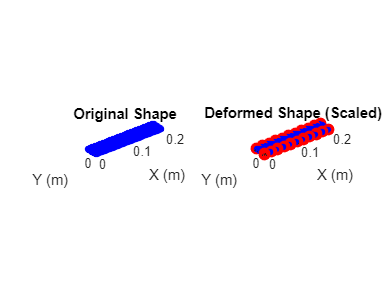


% Visualization force components
Fx_vis = zeros(size(x)); % No forces in x-direction
Fy_vis = zeros(size(y)); % Forces in y-direction (inward)
Fz_vis = zeros(size(z)); % No forces in z-direction

% Assign forces to Fy_vis for visualization
Fy_vis(force_nodes_bottom) = force_magnitude; % Bottom edge: upward (positive y)
Fy_vis(force_nodes_top) = -force_magnitude;  % Top edge: downward (negative y)

% Offset for origins
offset = 0.002; % Offset distance for visualization

% Adjust y-coordinates for origins
x_vis = x; % x-coordinates remain the same
z_vis = z; % z-coordinates remain the same
y_vis = y; % Copy original y-coordinates
y_vis(force_nodes_bottom) = y_vis(force_nodes_bottom) - offset; % Bottom edge: offset downward
y_vis(force_nodes_top) = y_vis(force_nodes_top) + offset;       % Top edge: offset upward

% Plotting the original plate and forces
figure;

% Original shape (blue grid points)
subplot(1, 2, 1);
scatter3(x, y, z, 10, 'b', 'filled'); % Plate grid points
xlabel('X (m)');
ylabel('Y (m)');
zlabel('Z (m)');
title('Original Shape');
grid on;
axis equal;

% Deformed shape (forces as red arrows pressing inward)
subplot(1, 2, 2);
scatter3(x, y, z, 10, 'b', 'filled'); % Original grid points in blue
hold on;

% Highlight nodes with forces applied
scatter3(x(force_nodes_bottom), y(force_nodes_bottom), z(force_nodes_bottom), 50, 'r', 'filled'); % Bottom edge
scatter3(x(force_nodes_top), y(force_nodes_top), z(force_nodes_top), 50, 'r', 'filled'); % Top edge

% Plot inward-pressing force arrows
quiver3(x_vis(force_nodes_bottom), y_vis(force_nodes_bottom), z_vis(force_nodes_bottom), ...
        Fx_vis(force_nodes_bottom), Fy_vis(force_nodes_bottom), Fz_vis(force_nodes_bottom), ...
        'k', 'LineWidth', 1.5, 'MaxHeadSize', 0.5); % Bottom edge forces

quiver3(x_vis(force_nodes_top), y_vis(force_nodes_top), z_vis(force_nodes_top), ...
        Fx_vis(force_nodes_top), Fy_vis(force_nodes_top), Fz_vis(force_nodes_top), ...
        'k', 'LineWidth', 1.5, 'MaxHeadSize', 0.5); % Top edge forces

xlabel('X (m)');
ylabel('Y (m)');
zlabel('Z (m)');
title('Deformed Shape (Scaled)');
grid on;
axis equal;
view(3); % Set 3D view
hold off;

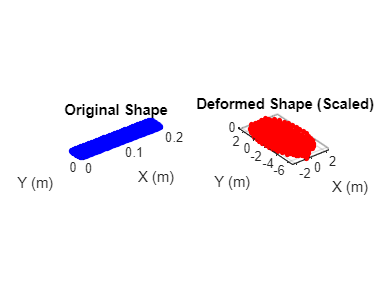


% Find fixed nodes (boundary conditions at x = 0 and x = L)
tolerance = 1e-6;  % Numerical tolerance for comparison
fixed_nodes = find(abs(node_coords(:, 1)) < tolerance | abs(node_coords(:, 1) - L) < tolerance);

% Map fixed nodes to DOFs (3 DOFs per node: x, y, z)
fixed_DOFs = [];
for node = fixed_nodes'
    fixed_DOFs = [fixed_DOFs, (node - 1) * 3 + (1:3)];
end

% Solve for Deflections (U = K^-1 * F)
% Extract free degrees of freedom (excluding fixed DOFs)
all_dofs = 1:(3 * num_nodes);
free_dofs = setdiff(all_dofs, fixed_DOFs);

% Partition the matrices: solve only for free DOFs
K_ff = K_global(free_dofs, free_dofs); % Submatrix for free DOFs
F_f = F_global(free_dofs);             % Reduced force vector

% Solve for displacements (deflections) at free DOFs
U_f = K_ff \ F_f;

% Initialize full displacement vector (including fixed DOFs)
U_global = zeros(3 * num_nodes, 1);
U_global(free_dofs) = U_f;

% Extract individual displacement components (x, y, z directions)
U_x = U_global(1:3:end); % Displacement in x-direction
U_y = U_global(2:3:end); % Displacement in y-direction
U_z = U_global(3:3:end); % Displacement in z-direction

% Reshape displacement vectors for easier plotting
U_x_reshaped = reshape(U_x, num_nodes_y, num_nodes_x, num_nodes_z);
U_y_reshaped = reshape(U_y, num_nodes_y, num_nodes_x, num_nodes_z);
U_z_reshaped = reshape(U_z, num_nodes_y, num_nodes_x, num_nodes_z);

% Reshape coordinates for plotting
X_reshaped = reshape(node_coords(:, 1), num_nodes_y, num_nodes_x, num_nodes_z);
Y_reshaped = reshape(node_coords(:, 2), num_nodes_y, num_nodes_x, num_nodes_z);
Z_reshaped = reshape(node_coords(:, 3), num_nodes_y, num_nodes_x, num_nodes_z);

% Scale factor for visualization (magnifies deflections for better visualization)
scale_factor = 1000;

% Visualization of the Original and Deformed Shapes
figure;

% Plot Original Shape
subplot(1, 2, 1);
scatter3(node_coords(:, 1), node_coords(:, 2), node_coords(:, 3), 10, 'b', 'filled');
title('Original Shape');
xlabel('X (m)');
ylabel('Y (m)');
zlabel('Z (m)');
grid on;
axis equal;

% Plot Deformed Shape
subplot(1, 2, 2);
scatter3(X_reshaped(:) + scale_factor * U_x_reshaped(:), ...
         Y_reshaped(:) + scale_factor * U_y_reshaped(:), ...
         Z_reshaped(:) + scale_factor * U_z_reshaped(:), ...
         10, 'r', 'filled');
title('Deformed Shape (Scaled)');
xlabel('X (m)');
ylabel('Y (m)');
zlabel('Z (m)');
grid on;
axis equal;
hold on;

% Overlay quiver plot for displacements
quiver3(X_reshaped(:), Y_reshaped(:), Z_reshaped(:), ...
        scale_factor * U_x_reshaped(:), ...
        scale_factor * U_y_reshaped(:), ...
        scale_factor * U_z_reshaped(:), ...
        'k');
hold off;


function [J_det, B, N, dN_dxyz]=brick8_Td(V,r,s,t)
x=V(:,1); 
y=V(:,2); 
z=V(:,3);
N = 1/8 * [
        (1 - r) * (1 - s) * (1 + t);
        (1 - r) * (1 - s) * (1 - t);
        (1 - r) * (1 + s) * (1 - t);
        (1 - r) * (1 + s) * (1 + t);
        (1 + r) * (1 - s) * (1 + t);
        (1 + r) * (1 - s) * (1 - t);
        (1 + r) * (1 + s) * (1 - t);
        (1 + r) * (1 + s) * (1 + t)
    ]; 
%     % Derivatives of shape functions with respect to r, s, t
    d_N_r = 1/8 * [
        -(1 - s) * (1 + t);
        -(1 - s) * (1 - t);
        -(1 + s) * (1 - t);
        -(1 + s) * (1 + t);
        (1 - s) * (1 + t);
        (1 - s) * (1 - t);
        (1 + s) * (1 - t);
        (1 + s) * (1 + t)
    ];
    d_N_s = 1/8 * [
        -(1 - r) * (1 + t);
        -(1 - r) * (1 - t);
        (1 - r) * (1 - t);
        (1 - r) * (1 + t);
        -(1 + r) * (1 + t);
        -(1 + r) * (1 - t);
        (1 + r) * (1 - t);
        (1 + r) * (1 + t)
    ];
    d_N_t = 1/8 * [
        (1 - r) * (1 - s);
        -(1 - r) * (1 - s);
        -(1 - r) * (1 + s);
        (1 - r) * (1 + s);
        (1 + r) * (1 - s);
        -(1 + r) * (1 - s);
        -(1 + r) * (1 + s);
        (1 + r) * (1 + s)
    ];
J=[x'*d_N_r y'*d_N_r z'*d_N_r;...
   x'*d_N_s y'*d_N_s z'*d_N_s;...  
   x'*d_N_t y'*d_N_t z'*d_N_t];
J_det = det(J);

d_N_x=zeros(8,1);
d_N_y=zeros(8,1);
d_N_z=zeros(8,1);
for i=1:1:8                                          
    NN =J \ [d_N_r(i) ; d_N_s(i) ; d_N_t(i)];
    d_N_x(i)=NN(1);
    d_N_y(i)=NN(2);
    d_N_z(i)=NN(3);
end

% Initialisierung der Matrix für globale Ableitungen (8x3)
dN_dxyz = zeros(3, 8); % [∂N/∂x, ∂N/∂y, ∂N/∂z] für jeden Knoten
% Berechnung der globalen Ableitungen
for i = 1:8
    % Lokale Ableitungen des i-ten Knotens
    dN_local = [d_N_r(i); d_N_s(i); d_N_t(i)];
    
    % Transformation der lokalen in globale Ableitungen
    dN_global = J\dN_local;
    
    % Speichern der Ableitungen in den jeweiligen Vektoren :
    d_N_x(i) = dN_global(1); % ∂N/∂x
    d_N_y(i) = dN_global(2); % ∂N/∂y
    d_N_z(i) = dN_global(3); % ∂N/∂z
    
    % Speichern in der Matrix dN_dxyz
    dN_dxyz(:, i) = dN_global'; % Als Zeile speichern
end

B=[ d_N_x(1) 0       0     d_N_x(2)    0    0    d_N_x(3)    0    0    d_N_x(4)    0    0    d_N_x(5)    0    0    d_N_x(6)    0    0    d_N_x(7)    0    0    d_N_x(8)    0    0 ;...
    0    d_N_y(1)    0     0    d_N_y(2)    0    0    d_N_y(3)    0    0    d_N_y(4)    0    0    d_N_y(5)    0    0    d_N_y(6)    0    0    d_N_y(7)    0    0    d_N_y(8)    0 ;...
    0    0    d_N_z(1)     0    0    d_N_z(2)    0    0    d_N_z(3)    0    0    d_N_z(4)    0    0    d_N_z(5)    0    0    d_N_z(6)    0    0    d_N_z(7)    0    0    d_N_z(8) ;...
    d_N_y(1) d_N_x(1) 0    d_N_y(2) d_N_x(2) 0   d_N_y(3) d_N_x(3) 0   d_N_y(4) d_N_x(4) 0   d_N_y(5) d_N_x(5) 0   d_N_y(6) d_N_x(6) 0   d_N_y(7) d_N_x(7) 0   d_N_y(8) d_N_x(8) 0;...
    0 d_N_z(1) d_N_y(1)    0 d_N_z(2) d_N_y(2)   0 d_N_z(3) d_N_y(3)   0 d_N_z(4) d_N_y(4)   0 d_N_z(5) d_N_y(5)   0 d_N_z(6) d_N_y(6)   0 d_N_z(7) d_N_y(7)   0 d_N_z(8) d_N_y(8);...
    d_N_z(1) 0 d_N_x(1)    d_N_z(2) 0 d_N_x(2)   d_N_z(3) 0 d_N_x(3)   d_N_z(4) 0 d_N_x(4)   d_N_z(5) 0 d_N_x(5)   d_N_z(6) 0 d_N_x(6)   d_N_z(7) 0 d_N_x(7)   d_N_z(8) 0 d_N_x(8)];
    
end
